[header1, seq1] = fastaread('/Users/aadithkrishna/Desktop/bio project/beta_covid (2).txt');
fprintf(seq1);

ATTAAAGGTTTATACCTTCCCAGGTAACAAACCAACCAACTTTCGATCTCTTGTAGATCTGTTCTCTAAACGAACTTTAAAATCTGTGTGGCTGTCACTCGGCTGCATGCTTAGTGCACTCACGCAGTATAATTAATAACTAATTACTGTCGTTGACAGGACACGAGTAACTCGTCTATCTTCTGCAGGCTGCTTACGGTTTCGTCCGTGTTGCAGCCGATCATCAGCACATCTAGGTTTCGTCCGGGTGTGACCGAAAGGTAAGATGGAGAGCCTTGTCCCTGGTTTCAACGAGAAAACACACGTCCAACTCAGTTTGCCTGTTTTACAGGTTCGCGACGTGCTCGTACGTGGCTTTGGAGACTCCGTGGAGGAGGTCTTATCAGAGGCACGTCAACATCTTAAAGATGGCACTTGTGGCTTAGTAGAAGTTGAAAAAGGCGTTTTGCCTCAACTTGAACAGCCCTATGTGTTCATCAAACGTTCGGATGCTCGAACTGCACCTCATGGTCATGTTATGGTTGAGCTGGTAGCAGAACTCGAAGGCATTCAGTACGGTCGTAGTGGTGAGACACTTGGTGTCCTTGTCCCTCATGTGGGCGAAATACCAGTGGCTTACCGCAAGGTTCTTCTTCGTAAGAACGGTAATAAAGGAGCTGGTGGCCATAGTTACGGCGCCGATCTAAAGTCATTTGACTTAGGCGACGAGCTTGGCACTGATCCTTATGAAGATTTTCAAGAAAACTGGAACACTAAACATAGCAGTGGTGTTACCCGTGAACTCATGCGTGAGCTTAACGGAGGGGCATACACTCGCTATGTCGATAACAACTTCTGTGGCCCTGATGGCTACCCTCTTGAGTGCATTAAAGACCTTCTAGCACGTGCTGGTAAAGCTTCATGCACTTTGTCCGAACAACTGGACTTTATTGACACTAAGAGGGGTGTATACTGCTGCCGTGAACATGAGCATGAAATTGCTTGGTACACGGAACGTTCT

fprintf('The CGR matrix for SARS cov-2 genetic sequence');

The CGR matrix for SARS cov-2 genetic sequence

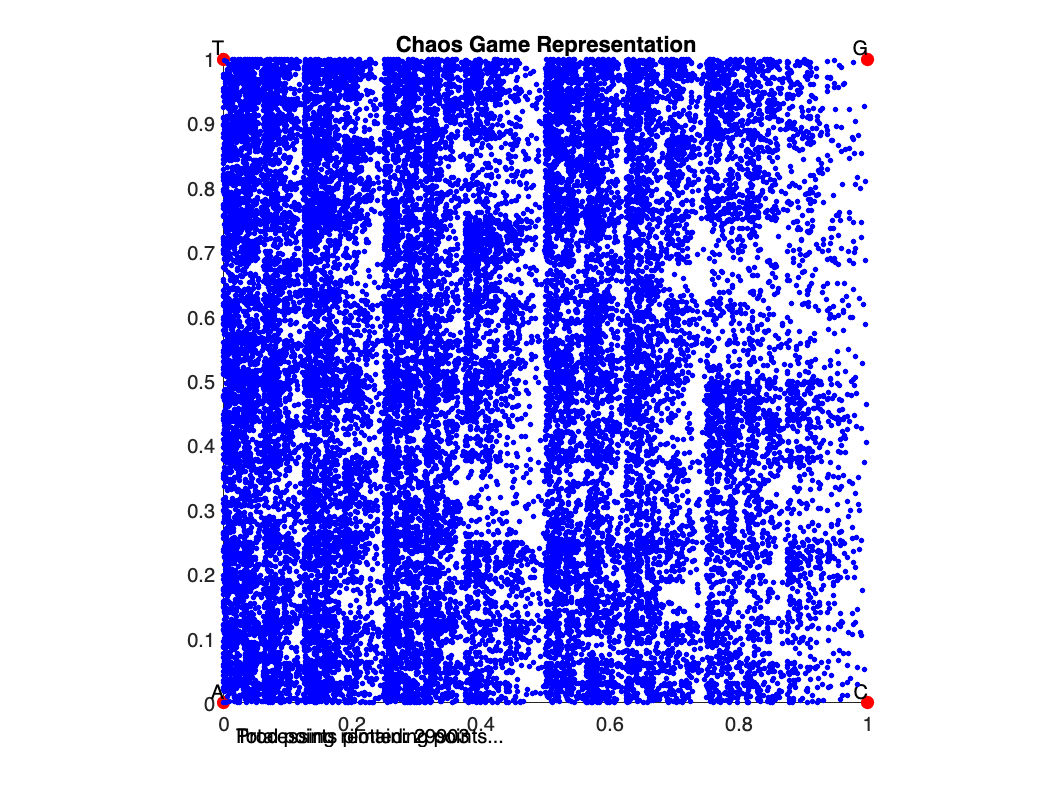




hybridCGR(seq1)

[header2, seq2] = fastaread('/Users/aadithkrishna/Desktop/bio project/sample1.txt');
fprintf(seq2);

ATTAAAGGTTTATACCTTTCCAGGTAACAAACCAACGAACTCTCGATCTCTTGTAGATCTGTTCTCTAAACGAACTTTAAAATCTGTGTGACTGTCACTCGGCTGCATGCTTAGTGCACTCACGCAGTATAATTAATAACTAATTACTGTCGTTGACAGGACACGAGTAACTCATCTATCTTCTGCAGGTTGCTTACGGTTTCGTCCGTGTTGCAGCCGATCATCAGCACATCTAGGTTTCGTCCGGGTGTGACCGAAAGGTAAGATGGAGAGCCTTGTCCCTGGTTTCAACGAGAAAACACACGTCCAACTCAGTTTGCCTGTCTTACAGGTTCGCGACGTGCTCGTACGTGGCTTTGGAGACTCCGTGGAGGAGGCTTTATCAGAGGCACGTCAACATCTTAAAGATGGCACTTGTGGCTTAGTAGAAGTTGAAAAAGGTGTTTTGCCTCAACTTGAACAGCCCTATGTGTTCATCAAACGTTCTGATGCTCGAACTGCACCTCATGGCCATGTTATGGTTGAGCTGGTAGCAGAACTTAATGGCATTCAGTATGGTCGTAGTGGTGAGACACTCGGTGTCCTTGTCCCTTATGTGGGCGAAACACCAGTGGTTTACCGCAAGGTTCTTCTTCGTAAGAACGGTAATAAAGGAGCTGGTGGCCATAGTTACGGCGCTGATCTAAAGTCGTTTGACTTAGGCGACGAGCTTGGCACTGATCCTTATGAAGATTTTCAAGAAAACTGGAACACTAAACATAGCAGTGGTGTCACCCGTGATCTCATGCGTGAGCTTAATGGAGGAGCATACACTCGCTATGTCGATAACAACTTCTGTGGCCCTGATGGCTACCCTCTTGAGTGCATTAAAGACCTTCTAGCTCGTGCTGGTAAAGCTTCATGCACTTTGTCCGAACAACTGGACTTTATTGACACTAAAAGAGGTGTATACTGCTGTCGTGAACATGAGCATGAGATTGCTTGGTACACGGAACGTTCT

fprintf('The CGR matrix for sample genetic sequence');

The CGR matrix for sample genetic sequence

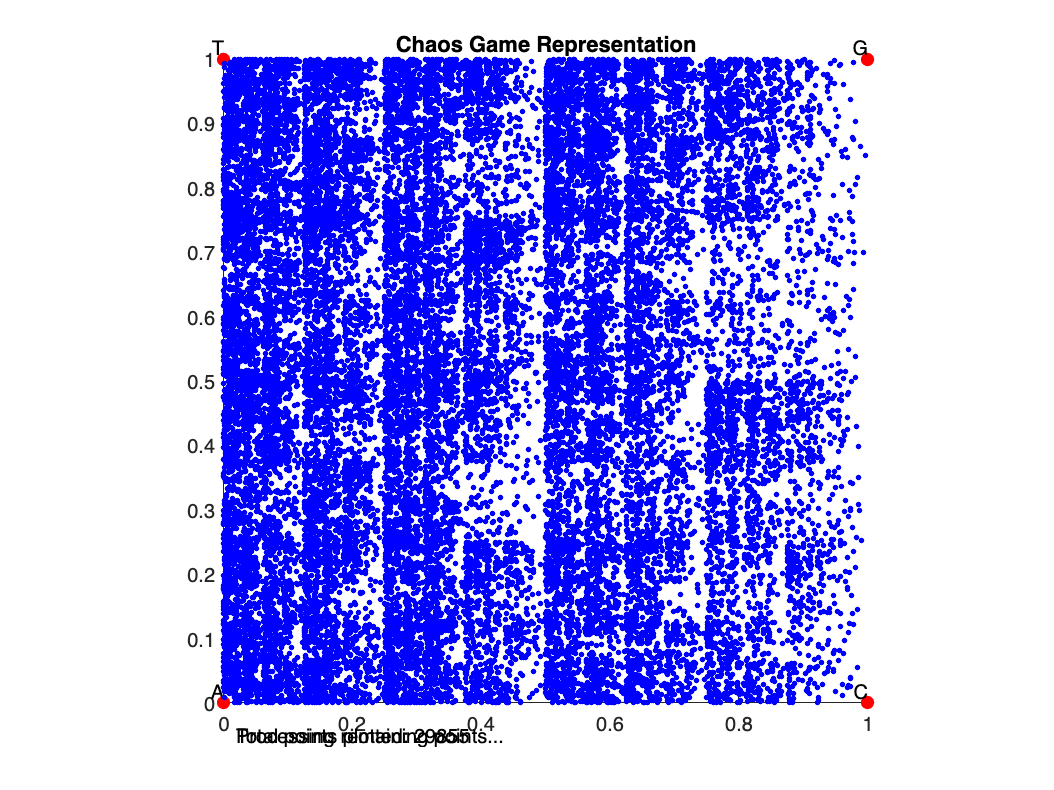




hybridCGR(seq2)

function hybridCGR(sequence)
    % Default delay between points if not specified
    if nargin < 2
        delay = 0.1; % seconds
    end
    
    % Animation threshold
    ANIMATION_LIMIT = 300;
    
    % Create figure and set properties
    figure('Color', 'white');
    hold on;
    axis square;
    axis([0 1 0 1]);
    title('Chaos Game Representation');
    
    % Define corner points for ACGT
    corners = containers.Map(...
        {'A', 'C', 'G', 'T'}, ...
        {[0 0], [1 0], [1 1], [0 1]});
    
    % Plot and label corner points
    cornerLabels = keys(corners);
    for i = 1:length(cornerLabels)
        label = cornerLabels{i};
        point = corners(label);
        plot(point(1), point(2), 'r.', 'MarkerSize', 20);
        text(point(1), point(2), label, ...
            'VerticalAlignment', 'bottom', ...
            'HorizontalAlignment', 'right');
    end
    
    % Initialize starting point at center
    currentPoint = [0.5 0.5];
    allPoints = zeros(length(sequence), 2);  % Pre-allocate array for all points
    pointCount = 0;
    
    % First phase: Animated plotting (first 2000 points)
    animationLimit = min(ANIMATION_LIMIT, length(sequence));
    
    % Process first 2000 nucleotides with animation
    for i = 1:animationLimit
        nucleotide = upper(sequence(i));
        
        if ~isKey(corners, nucleotide)
            warning('Invalid nucleotide %s at position %d - skipping', nucleotide, i);
            continue;
        end
        
        targetCorner = corners(nucleotide);
        newPoint = (currentPoint + targetCorner) / 2;
        
        plot(newPoint(1), newPoint(2), 'b.', 'MarkerSize', 8);
        
        % Store point
        pointCount = pointCount + 1;
        allPoints(pointCount, :) = newPoint;
        currentPoint = newPoint;
        
        % Update progress
        if mod(i, 10) == 0
            progressText = sprintf('Animated points: %d/%d', i, animationLimit);
            if exist('textHandle', 'var')
                delete(textHandle);
            end
            textHandle = text(0.02, -0.05, progressText, ...
                'Units', 'normalized');
        end
        
        pause(delay);
        drawnow;
    end
    
    % Second phase: Rapid plotting (remaining points)
    if length(sequence) > ANIMATION_LIMIT
        if exist('textHandle', 'var')
            delete(textHandle);
        end
        text(0.02, -0.05, 'Processing remaining points...', ...
            'Units', 'normalized');
        
        % Process remaining nucleotides without animation
        for i = (animationLimit + 1):length(sequence)
            nucleotide = upper(sequence(i));
            
            if ~isKey(corners, nucleotide)
                continue;
            end
            
            targetCorner = corners(nucleotide);
            newPoint = (currentPoint + targetCorner) / 2;
            currentPoint = newPoint;
            
            % Store point
            pointCount = pointCount + 1;
            allPoints(pointCount, :) = newPoint;
        end
        
        % Plot all remaining points at once
        plot(allPoints((animationLimit+1):pointCount, 1), ...
             allPoints((animationLimit+1):pointCount, 2), ...
             'b.', 'MarkerSize', 8);
    end
    
    % Final progress update
    if exist('textHandle', 'var')
        delete(textHandle);
    end
    text(0.02, -0.05, sprintf('Total points plotted: %d', pointCount), ...
        'Units', 'normalized');
    
    hold off;
end



% Example with specific sequence:
% sequence = [repmat('ACGT', 1, 500), repmat('AG', 1, 4000)];  % 2000 + 8000 nucleotides
% hybridCGR(sequence, 0.01);